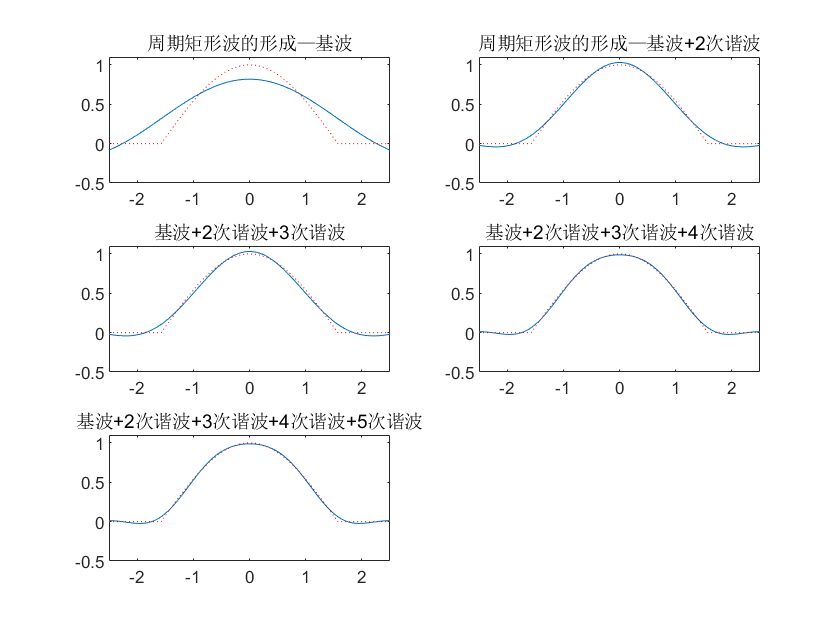

clear;
syms t f n t0;
T=2*pi;
tao_2=pi;
Nf=7;
Nn=6;
f = (abs(cos(t))+cos(t))/2;
figure(1);
%plot(t,f);
figure(2);
A0=int(f,t,-tao_2,T-tao_2)/T;
As=int(f*2*cos(2*pi*n*t/T)/T,t,-tao_2,T-tao_2);
Bs=int(f*2*sin(2*pi*n*t/T)/T,t,-tao_2,T-tao_2);
Fn=(As-1i*Bs)/2;
A(1)=double(vpa(A0,Nn));
for k=1:Nf
     A(k+1)=double(vpa(subs(As,n,k),Nn));
     B(k+1)=double(vpa(subs(Bs,n,k),Nn));
end

t1=-T/2:0.01:T/2;
f1=A(1)+A(2).*cos(2*pi*1*t1/T)+B(2)*sin(2*pi*1*t1/T);      % 基波
f2=A(3).*cos(2*pi*2*t1/T)+B(3)*sin(2*pi*2*t1/T);           % 2次谐波
f3=A(4).*cos(2*pi*3*t1/T)+B(4).*sin(2*pi*3*t1/T);          % 3次谐波
f4=A(5).*cos(2*pi*4*t1/T)+B(5).*sin(2*pi*4*t1/T);          % 4次谐波
f5=A(6).*cos(2*pi*5*t1/T)+B(6).*sin(2*pi*5*t1/T);          % 5次谐波
y=subs(f,t,t1);         %调用连续时间函数-周期矩形脉冲
f12=f1+f2;                      % 基波+2次谐波
f123=f12+f3;                     % 基波+2次谐波+3次谐波
f1234=f1+f2+f3+f4;
f12345=f123+f4+f5;                 % 基波+2次谐波+3次谐波+4次谐波+6次谐波 
subplot(3,2,1),plot(t1,f1),hold on;plot(t1,y,'r:');title('周期矩形波的形成—基波'),axis([-2.5,2.5,-0.5,1.1]);
subplot(3,2,2),plot(t1,f12),hold on;plot(t1,y,'r:');title('周期矩形波的形成—基波+2次谐波'),axis([-2.5,2.5,-0.5,1.1]);
subplot(3,2,3),plot(t1,f123),hold on;plot(t1,y,'r:');title('基波+2次谐波+3次谐波'),axis([-2.5,2.5,-0.5,1.1]);
subplot(3,2,4),plot(t1,f1234),hold on;plot(t1,y,'r:');title('基波+2次谐波+3次谐波+4次谐波'),axis([-2.5,2.5,-0.5,1.1]);
subplot(3,2,5),plot(t1,f12345),hold on;plot(t1,y,'r:');title('基波+2次谐波+3次谐波+4次谐波+5次谐波'),axis([-2.5,2.5,-0.5,1.1]);